# Dimensionering af en varmepumpe til kraftvarmeværk

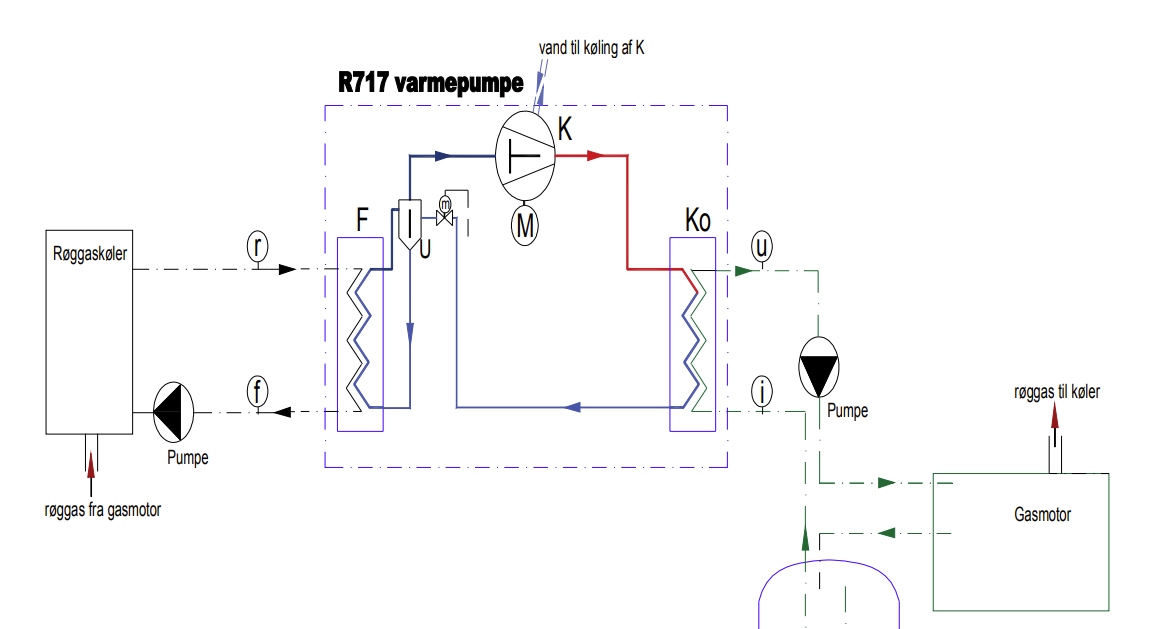

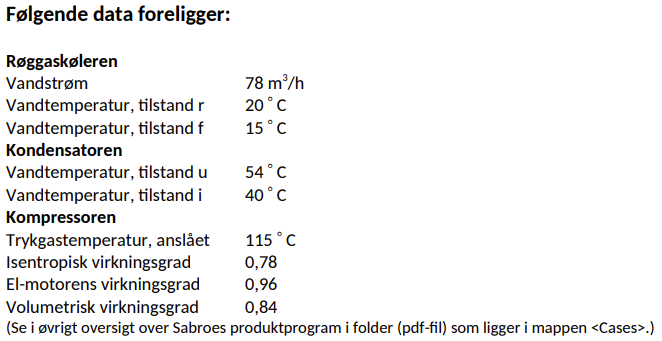

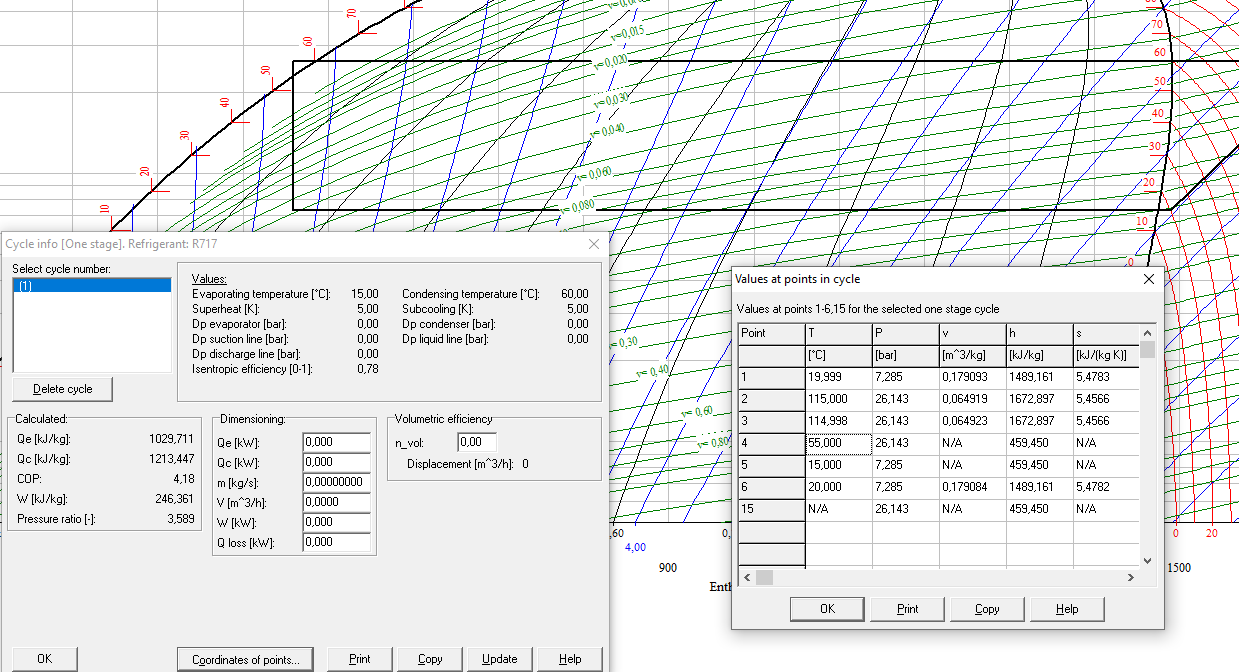

clc; clear all;
u = symunit;


%----------------------------------------------%
%--------------- Røggaskøleren ----------------%
%----------------------------------------------%
q_V = 78 * u.m^3/u.h;
rho_V = 999.1 * u.kg/u.m^3;
cp_V = 4182 * u.J/(u.kg*u.K);

t_r = 20*u.K;
t_f = 15*u.K;


phi_RK = q_V*rho_V*cp_V*(t_r - t_f);
phi_RK = vpa(unitConvert(phi_RK, u.kW), 6)

$$phi\_RK = 452.642\,\mathrm{kW}$$

$$phi\_komp\_cool = 40.404\,\mathrm{kW}$$

$$qV\_vand = 0.669471\,\frac{m^{3}}{h}$$

% Entalper
h1 = 1489.161 *u.kJ/u.kg;
h2 = 1672.9*u.kJ/u.kg;
h3 = 459.45*u.kJ/u.kg;
h4 = h3;

h5 = 1735.522*u.kJ/u.kg % ikke kølet kompressor

$$h5 = \frac{1908226619261059}{1099511627776}\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$




super = 1491.49*u.kJ/u.kg;
konding = 485.03*u.kJ/u.kg;
subbing = 459.19*u.kJ/u.kg;

Phi0 = phi_RK;


q_mr = Phi0/(h1 - h4);
q_mr = vpa(unitConvert(q_mr, "SI"), 3)

$$q\_mr = 0.44\,\frac{\mathrm{kg}}{s}$$


Pel = q_mr*(h5-h1);
Pel = vpa(unitConvert(Pel, u.kW), 6)

$$Pel = 108.296\,\mathrm{kW}$$


phi_komp_cool = q_mr*(h5-h2);
phi_komp_cool = vpa(unitConvert(phi_komp_cool, u.kW),5)

$$phi\_komp\_cool = 27.527\,\mathrm{kW}$$


% Vandstrøm omkring kompressor
T_v_ind_komp = 18*u.K;
T_v_ud_komp = 70*u.K; % Det skal bruges til fjernvarme og skulle gerne være samme temp som det der kommer ned i akk. tanken

syms qV_vand

rho_V = 999.1 * u.kg/u.m^3;
cp_V = 4182 * u.J/(u.kg*u.K);

eq = phi_komp_cool == qV_vand*rho_V*cp_V*(T_v_ud_komp - T_v_ind_komp);

qV_vand = solve(eq, qV_vand);
qV_vand = vpa(unitConvert(qV_vand, u.m^3/u.h),6)

$$qV\_vand = 0.456113\,\frac{m^{3}}{h}$$



% Henover kompressor
kompressor = vpa(unitConvert(q_mr*(h1-h2), u.kW), 4)

$$kompressor = -80.77\,\mathrm{kW}$$


% Henover kondensator
kondensator = vpa(unitConvert(q_mr*(h2-h3), u.kW), 6)

$$kondensator = 533.411\,\mathrm{kW}$$


kond_desuper = vpa(unitConvert(q_mr*(h2-super), u.kW), 6)

$$kond\_desuper = 79.7445\,\mathrm{kW}$$

kond_konding = vpa(unitConvert(q_mr*(super-konding), u.kW), 6)

$$kond\_konding = 442.422\,\mathrm{kW}$$

kond_subbing = vpa(unitConvert(q_mr*(konding - subbing), u.kW), 6)

$$kond\_subbing = 11.3588\,\mathrm{kW}$$


kond_total = vpa(kond_desuper+kond_konding+kond_subbing, 6)

$$kond\_total = 533.525\,\mathrm{kW}$$


% Ekspansionsventil
epv = vpa(unitConvert(q_mr*(h3-h4), u.kW), 4)

$$epv = 0.0$$


% Fordamper
fordamper = vpa(unitConvert(q_mr*(h4-h1), u.kW), 4)

$$fordamper = -452.6\,\mathrm{kW}$$



% NH3
t_nh3_ind = 115*u.K;
t_nh3_ud = 60*u.K;
% t_nh3_ud = 60*u.K; % ANTAGET VÆRDI

cp_NH3 = 2.881 * u.kJ/(u.kg*u.K);
rho_NH3 = 15.47 * u.kg/u.m^3;

eta_v = 0.84;
%q_Vs_komp = 2000 * u.m^3/u.h; % Valgt ud fra casen
syms q_Vs_komp

qV_NH3 = eta_v * q_Vs_komp;
qV_NH3 = vpa(unitConvert(qV_NH3, u.m^3/u.h), 3);

eq = kondensator == qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ind - t_nh3_ud);


q_Vs_komp = solve(eq, q_Vs_komp);
q_Vs_komp = vpa(unitConvert(q_Vs_komp, u.m^3/u.h), 3)

$$q\_Vs\_komp = 933.0\,\frac{m^{3}}{h}$$


% Volumenstrøm af vand i kondensator
t_kond_vi = 40 * u.K;
t_kond_vu = 54 * u.K;

syms qV_vand_kond
phi_kond_vand = qV_vand_kond*rho_V*cp_V*(t_kond_vu - t_kond_vi);

eq = kondensator == phi_kond_vand;

qV_vand_kond = solve(eq, qV_vand_kond);
qV_vand_kond = vpa(unitConvert(qV_vand_kond, u.m^3/u.h), 3)

$$qV\_vand\_kond = 32.8\,\frac{m^{3}}{h}$$

## Rørdimensioner

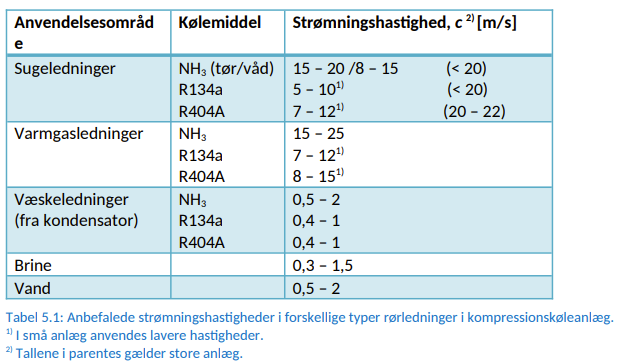

% Sugeledninger til kondensator
c1 = 17.5 * u.m/u.s;
NH3_ind = q_Vs_komp;

A1 = NH3_ind/c1;
A1 = vpa(unitConvert(A1, "SI"), 3);
A1 = vpa(unitConvert(A1, u.cm^2), 3)

$$A1 = 148.0\,{\mathrm{cm}}^{2}$$


cA1 = vpa(sqrt(A1/pi), 3)

$$cA1 = 6.86\,\mathrm{cm}$$





% Varmgasledninger
c2 = 20 * u.m/u.s;
NH3_ind = q_Vs_komp;

A2 = NH3_ind/c2;
A2 = vpa(unitConvert(A2, "SI"), 3);
A2 = vpa(unitConvert(A2, u.cm^2), 3)

$$A2 = 130.0\,{\mathrm{cm}}^{2}$$


cA2 = vpa(sqrt(A2/pi), 3)

$$cA2 = 6.42\,\mathrm{cm}$$


% Væskeledninger fra kondensator efter EPV
c3 = 1.25 * u.m/u.s;

NH3_ind = q_Vs_komp;

A3 = NH3_ind/c3;
A3 = vpa(unitConvert(A3, "SI"), 3);
A3 = vpa(unitConvert(A3, u.cm^2), 3)

$$A3 = 2070.0\,{\mathrm{cm}}^{2}$$


cA3 = vpa(sqrt(A3/pi), 3)

$$cA3 = 25.7\,\mathrm{cm}$$




U = 1000 * u.W/(u.m^2*u.K) % første gæt mellem 500-1500

$$U = 1000\,\frac{W}{K\,m^{2}}$$


% NH3
t_nh3_ind = 115 *u.K;
t_nh3_ud = t_nh3_ud; % ANTAGET VÆRDI

% Vand
t_kond_vi = 40 * u.K;
t_kond_vu = 54 * u.K;

% LMTD
LMTD = ((t_nh3_ind - t_kond_vi) - (t_nh3_ud - t_kond_vu))/(log((t_nh3_ind - t_kond_vi)/(t_nh3_ud - t_kond_vu)));
LMTD = vpa(unitConvert(LMTD, "SI"), 3)

$$LMTD = 27.3\,K$$



% Varmevekslende areal
A = phi_kond_NH3/(U * LMTD);

Unrecognized
function
or
variable
'phi_kond_NH3'.

A = vpa(unitConvert(A, "SI"), 3)

% Strømningshastighed fra kondensator
cv_NH3 = 1.25 * u.m/u.s;





syms Phi_v qV_v rho_v cp_v t_vu t_fi

% Phi for vand ved kondensator
Phi_v = qV_v*rho_v*cp_v*(t_vu*t_fi)


% Phi for NH3 ved kondensator
syms Phi_NH3 qV_NH3 rho_NH3 cp_NH3 t_NH3_vu t_NH3_fi
Phi_NH3 = qV_NH3*rho_NH3*cp_NH3*(t_NH3_vu*t_NH3_fi)

% Hastighed fra kondensator ????
d_fordamp = 20*u.mm;

c_fordamp = 4*qV_NH3/(pi*d_fordamp^2);
c_fordamp = vpa(unitConvert(c_fordamp,"SI"), 3)

clc; clear all;
u = symunit;

h1 = 1489.161 *u.kJ/u.kg;
h2 = 1672.9*u.kJ/u.kg;
h3 = 459.45*u.kJ/u.kg;
h4 = h3;

h5 = 1735*u.kJ/u.kg;

Phi0 = 453*u.kW;


q_mr = Phi0/(h1 - h4);
q_mr = vpa(unitConvert(q_mr, "SI"), 3)



% Henover kompressor
kompressor = vpa(unitConvert(q_mr*(h1-h2), u.kW), 4)

% Henover kondensator
kondensator = vpa(unitConvert(q_mr*(h2-h3), u.kW), 4)

% Ekspansionsventil
epv = vpa(unitConvert(q_mr*(h3-h4), u.kW), 4)

% Fordamper
fordamper = vpa(unitConvert(q_mr*(h4-h1), u.kW), 4)

% Køling over kompressor
cooling = vpa(unitConvert(q_mr*(h5-h4), u.kW), 4)



%----------------------------------------------%
%--------------- Kondensatoren ----------------%
%----------------------------------------------%


% NH3
t_nh3_ind = 115*u.K;
t_nh3_ud = 60*u.K;
% t_nh3_ud = 60*u.K; % ANTAGET VÆRDI

cp_NH3 = 2.881 * u.kJ/(u.kg*u.K);
rho_NH3 = 15.47 * u.kg/u.m^3;

eta_v = 0.84;
%q_Vs_komp = 2000 * u.m^3/u.h; % Valgt ud fra casen
syms q_Vs_komp

qV_NH3 = eta_v * q_Vs_komp;
qV_NH3 = vpa(unitConvert(qV_NH3, u.m^3/u.h), 3)

eq = kondensator == qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ind - t_nh3_ud);


q_Vs_komp = solve(eq, q_Vs_komp);
q_Vs_komp = vpa(unitConvert(q_Vs_komp, u.m^3/u.h), 3)



%----------------------------------------------%
%--------------- Kondensatoren ----------------%
%----------------------------------------------%


% NH3
t_nh3_ind = 115*u.K;
t_nh3_ud = 60*u.K; % ANTAGET VÆRDI

cp_NH3 = 2.881 * u.kJ/(u.kg*u.K);
rho_NH3 = 15.47 * u.kg/u.m^3;

eta_v = 0.84;
q_Vs_komp = 200 * u.m^3/u.h; % Valgt ud fra casen

qV_NH3 = eta_v * q_Vs_komp;
qV_NH3 = vpa(unitConvert(qV_NH3, u.m^3/u.h), 3)

phi_kond_NH3 = qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ind - t_nh3_ud);
phi_kond_NH3 = vpa(unitConvert(phi_kond_NH3, u.kW), 5)


% Vandstrømmen der køler

t_kond_vi = 40 * u.K;
t_kond_vu = 54 * u.K;

syms qV_vand_kond
phi_kond_vand = qV_vand_kond*rho_V*cp_V*(t_kond_vu - t_kond_vi);

eq = phi_kond_vand == phi_kond_NH3;

qV_vand_kond = solve(eq, qV_vand_kond);
qV_vand_kond = vpa(unitConvert(qV_vand_kond, u.m^3/u.h), 3)


test = qV_vand_kond * rho_V * cp_V * (t_kond_vu - t_kond_vi);
test = vpa(unitConvert(test, u.kW), 5)

syms t_udnu
eqq = qV_NH3 * rho_NH3 * cp_NH3 * (t_nh3_ind - t_udnu) == qV_vand_kond * rho_V * cp_V * (t_kond_vi - t_kond_vu);


